# Compensator Design Tools - INEL 5508

This script helps perform calculations, in turn saving a lot of time.

clear all;
close all;
clc;

% Open-loop system transfer Function
s = zpk('s');

% Sampling Time
T = 30E-3; % [seg]

K_m = 7;
G_m = 61 / (s * (s + 36));
G_bb = 0.4183 / s^2;

G1 = c2d(G_m, T, 'zoh');
G2 = c2d(G_m * G_bb, T, 'zoh');

G_p = minreal(K_m * G2 / (1 + K_m * G1));
G_p.Name = 'G_p';
G_p.InputName = 'E_s';
G_p.InputUnit = 'm';
G_p.OutputName = 'X_s';
G_p.OutputUnit = 'm';
G_p

G_p =
 
  From input "E_s" to output "X_s":
  4.9287e-06 (z+8.196) (z+0.8089) (z+0.07905)
  -------------------------------------------
        (z-1)^2 (z^2 - 1.201z + 0.4363)
 
Name: G_p
Sample time: 0.03 seconds
Discrete-time zero/pole/gain model.



% Desired performance characteristics

%O.S. <= 30%
percent_overshoot = 5; % [%]

% T_s <= 5 seg
settling_time = 3; % [seg]

% Choose zeta and omega_n
zeta_min = abs(log(percent_overshoot / 100)) / sqrt((log(percent_overshoot / 100))^2 + pi^2)

zeta_min = 0.6901

zeta = 0.7 %

zeta = 0.7000

omega_n_min = 4 / (zeta * settling_time)

omega_n_min = 1.9048

omega_n = 2.0 % [rad/s]

omega_n = 2


if zeta < zeta_min
    error("ζ is less than ζ_min!");
end
if omega_n < omega_n_min
    error("ω_n is less than ω_n_min!");
end

% Find second-order system reponse poles
omega_d = omega_n * sqrt(1 - zeta^2); % [rad/s]
continuous_desired_poles = [-zeta * omega_n + 1j*omega_d; -zeta * omega_n - 1j*omega_d];
discrete_desired_poles = exp(continuous_desired_poles * T)

discrete_desired_poles =    0.9580 + 0.0411i
   0.9580 - 0.0411i


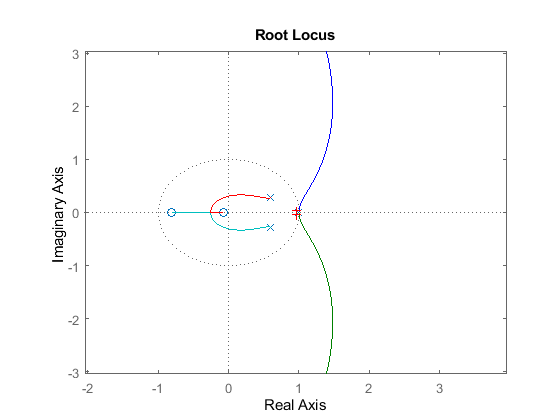


% Plot the root locus for the open-loop plant and the desired pole location
close all
hold on;
rlocus(G_p);
scatter(real(discrete_desired_poles'), imag(discrete_desired_poles'), 'r+');
rl_zoom = 3;
xlim([real(discrete_desired_poles(1)) - rl_zoom, real(discrete_desired_poles(1)) + rl_zoom]);
ylim([-abs(imag(discrete_desired_poles(1))) - rl_zoom, abs(imag(discrete_desired_poles(1))) + rl_zoom]);
hold off;

## Phase Lead Compensator

lead_compensator_zeroes = 0.965;

% Angular condition:
angle_condition = 0; % rad
for z_0 = zero(G_p)'
    angle_condition = angle_condition + angle(discrete_desired_poles(1) - z_0);    
end
for z_p = pole(G_p)'
    angle_condition = angle_condition - angle(discrete_desired_poles(1) - z_p);
end

% Convert to angle between -pi and pi [rad]
rad2deg(angle_condition)

ans = -275.7222

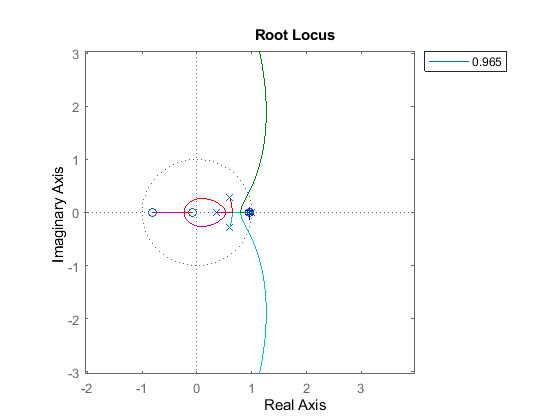

angle_condition = mod(angle_condition, pi);

functions_to_plot = [];
for lead_copmensator_zero = lead_compensator_zeroes
    % Calculate the lead compensator zero's theta and desired pole theta
    theta_zero = angle(discrete_desired_poles(1) - lead_copmensator_zero);
    theta_pole = theta_zero + angle_condition;
    
    % Show warning if zero is problematic
    if theta_pole < 0
        warning("theta_pole is less than 0 for zero in " + num2str(lead_copmensator_zero) + ", where the theta_zero is " + num2str(rad2deg(theta_zero)));
        continue;
    end
    
    % Calculate the lead compensator's pole location
    lead_compensator_pole = real(discrete_desired_poles(1)) - imag(discrete_desired_poles(1)) / tan(theta_pole);
    
    % Magnitude Condition
    lead_compensator_K = abs(discrete_desired_poles(1) - lead_compensator_pole) / abs(discrete_desired_poles(1) - lead_copmensator_zero);
    lead_compensator_K = lead_compensator_K / abs(evalfr(G_p, discrete_desired_poles(1)));
    
    % Lead compensator
    G_lead = zpk(lead_copmensator_zero, lead_compensator_pole, lead_compensator_K, T);
    
    % Plot function only if system is table
    if max(abs(zero(G_lead * G_p + 1))) <= 1 && sum(abs(zero(G_lead * G_p + 1)) == 1) <= 1
        functions_to_plot = [functions_to_plot; {num2str(lead_copmensator_zero), G_lead}];
    end    
end

if length(functions_to_plot) == 0
    error("No stable solutions were found.");
end

% Plot root loci
figure('Name', 'Root Loci');
hold on;
for compensated_plant = functions_to_plot(:,2)'
    rlocus(compensated_plant{1} * G_p);
end
scatter(real(discrete_desired_poles'), imag(discrete_desired_poles'), 'b+');
xlim([real(discrete_desired_poles(1)) - rl_zoom, real(discrete_desired_poles(1)) + rl_zoom]);
ylim([-abs(imag(discrete_desired_poles(1))) - rl_zoom, abs(imag(discrete_desired_poles(1))) + rl_zoom]);
hold off;
legend(functions_to_plot(:,1)', 'Location', "bestoutside");

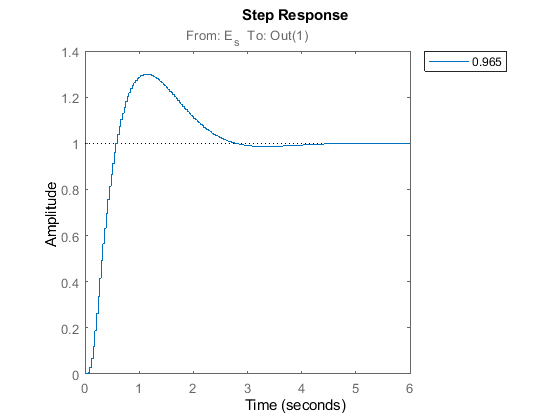


% Plot the closed-loop step response
figure('Name', 'Step Responses');
hold on;
for compensated_plant = functions_to_plot(:,2)'
    % `feedback` closes the loop correctly for the discrete-time system.
    step(feedback(compensated_plant{1} * G_p, 1));
end
hold off;
legend(functions_to_plot(:,1)', 'Location', "bestoutside");

## Phase Lag Compensator

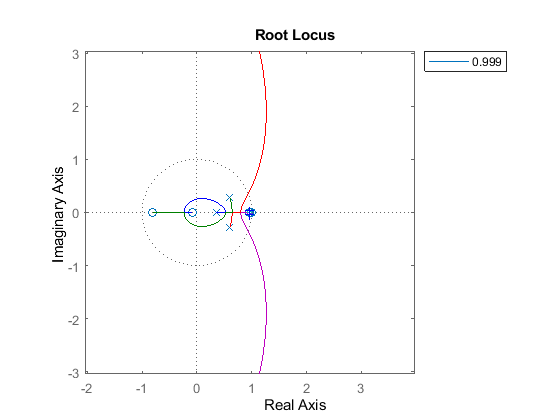

% We will reuse functions_to_plot
clear functions_to_plot

% Update the plant with the lead compensator you want to use
G_compensated = zpk(0.965, 0.365193637941580, 121.136307447243, T) * G_p;

% Determine K_d, which indicates how many times you want to reduce e_ss
n = 1.5;

% Select a lag compensator pole, which must be close to z=1
lag_compensator_poles = 0.999;

% Calculate the lag compensator's zero
lag_compensator_zeroes = 1 - (1 - lag_compensator_poles) .* n;

functions_to_plot = [];
for idx = 1:length(lag_compensator_poles)
    % Skip cases where z_0 > z_p
    if lag_compensator_poles(idx) < lag_compensator_zeroes(idx)
        warning("For z_p = " + num2str(lag_compensator_poles(idx)) + ", the compensator is not a lag one");
        continue;
    end
    
    % Lag Compensator
    G_lag = zpk(lag_compensator_zeroes(idx), lag_compensator_poles(idx), 1/n, T);
    
    % Plot function only if system is table
    if max(abs(zero(G_lag * G_compensated + 1))) <= 1 && sum(abs(zero(G_lag * G_compensated + 1)) == 1) <= 1
        functions_to_plot = [functions_to_plot; {num2str(lag_compensator_poles(idx)), G_lag}];
    end  
end

% Plot root loci
figure('Name', 'Root Loci');
hold on;
for compensated_plant = functions_to_plot(:,2)'
    rlocus(compensated_plant{1} * G_compensated);
end
scatter(real(discrete_desired_poles'), imag(discrete_desired_poles'), 'b+');
xlim([real(discrete_desired_poles(1)) - rl_zoom, real(discrete_desired_poles(1)) + rl_zoom]);
ylim([-abs(imag(discrete_desired_poles(1))) - rl_zoom, abs(imag(discrete_desired_poles(1))) + rl_zoom]);
hold off;
legend(functions_to_plot(:,1)', 'Location', "bestoutside");

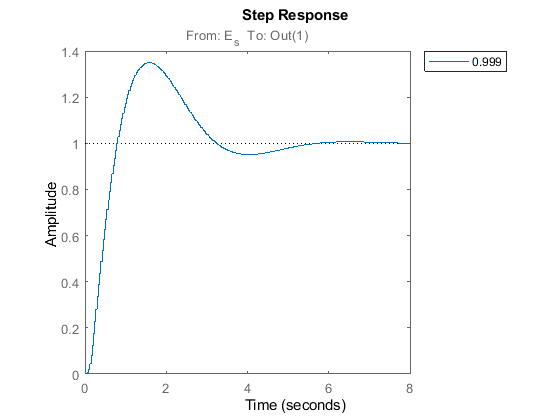


% Plot the closed-loop step response
figure('Name', 'Step Responses');
hold on;
for compensated_plant = functions_to_plot(:,2)'
    step(feedback(compensated_plant{1} * G_compensated, 1));
end
hold off;
legend(functions_to_plot(:,1)', 'Location', "bestoutside");

## Summary

Here are the lead and lag compensators that I chose to implement.

G_lead = zpk(0.965, 0.365193637941580, 121.136307447243, T)

G_lead =
 
  121.14 (z-0.965)
  ----------------
     (z-0.3652)
 
Sample time: 0.03 seconds
Discrete-time zero/pole/gain model.



G_lag = zpk([0.9985], [0.999], 1, T)

G_lag =
 
  (z-0.9985)
  ----------
  (z-0.999)
 
Sample time: 0.03 seconds
Discrete-time zero/pole/gain model.



G_c = G_lead * G_lag

G_c =
 
  121.14 (z-0.965) (z-0.9985)
  ---------------------------
     (z-0.3652) (z-0.999)
 
Sample time: 0.03 seconds
Discrete-time zero/pole/gain model.

